# Analyzing various water vapor measurements recorded during the VOCALS-REx flight campaign

Andrew John Buggee

## The VOCALS-REx flight campaign recorded water vapor several different ways

1) Absolute humidity: the mass of water vapor per unit volume of air.

2) Vapor Pressure: the partial pressure of water vapor in a unit volume of air

3) Mixing Ratio: the mass of water vapor per kg of dry air

## Read VOCALS-Rex data

clear variables 

%% Define the VOCALS-REx data paths for the machine you're using

% Determine which computer you're using

% Find the folder where the mie calculations are stored
% find the folder where the water cloud files are stored.
if strcmp(whatComputer,'anbu8374')==true

    % -----------------------------------------
    % ------ Folders on my Mac Desktop --------
    % -----------------------------------------

    %     % ***** Define the MODIS Folder *****
    %
    %     modisFolder = ['/Users/anbu8374/Documents/MATLAB/Matlab-Research/Hyperspectral_Cloud_Retrievals/',...
    %         'MODIS_Cloud_Retrieval/MODIS_data/'];

    % ***** Define the VOCALS-REx File *****

    vocalsRexFolder = ['/Users/anbu8374/Documents/MATLAB/Matlab-Research/Hyperspectral_Cloud_Retrievals/',...
        'VOCALS_REx/vocals_rex_data/SPS_1/'];

elseif strcmp(whatComputer,'andrewbuggee')==true

    % -------------------------------------
    % ------ Folders on my Macbook --------
    % -------------------------------------

    % ----- Define the MODIS folder name -----

    %     modisFolder = ['/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/Hyperspectral_Cloud_Retrievals/',...
    %         'MODIS_Cloud_Retrieval/MODIS_data/'];

    % ***** Define the VOCALS-REx Folder *****

    vocalsRexFolder = ['/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/Hyperspectral_Cloud_Retrievals/',...
        'VOCALS_REx/vocals_rex_data/SPS_1/'];

elseif strcmp(whatComputer,'curc')==true

    % ------------------------------------------------
    % ------ Folders on the CU Super Computer --------
    % ------------------------------------------------

    % Define the MODIS folder name

    %     modisFolder = '/projects/anbu8374/MODIS_data/';

    % ***** Define the VOCALS-REx Folder *****

    vocalsRexFolder = '/projects/anbu8374/VOCALS_REx_data/';


end


% *** Read VOCALS-REx data file ***

% ----- November 9 data -----
% vocalsRexFile = 'RF11.20081109.125700_213600.PNI.nc';

% ----- November 11 data -----
vocalsRexFile = 'RF12.20081111.125000_214500.PNI.nc';


vocalsRex = readVocalsRex([vocalsRexFolder,vocalsRexFile]);



## Convert Absolute Humidity to Number Concentration

$N_c = q' \, \frac{N_a}{M}$   where $q'$ is the absolute humidity, $N_a$ is Avogadro's number and $M$ is the molar mass of water

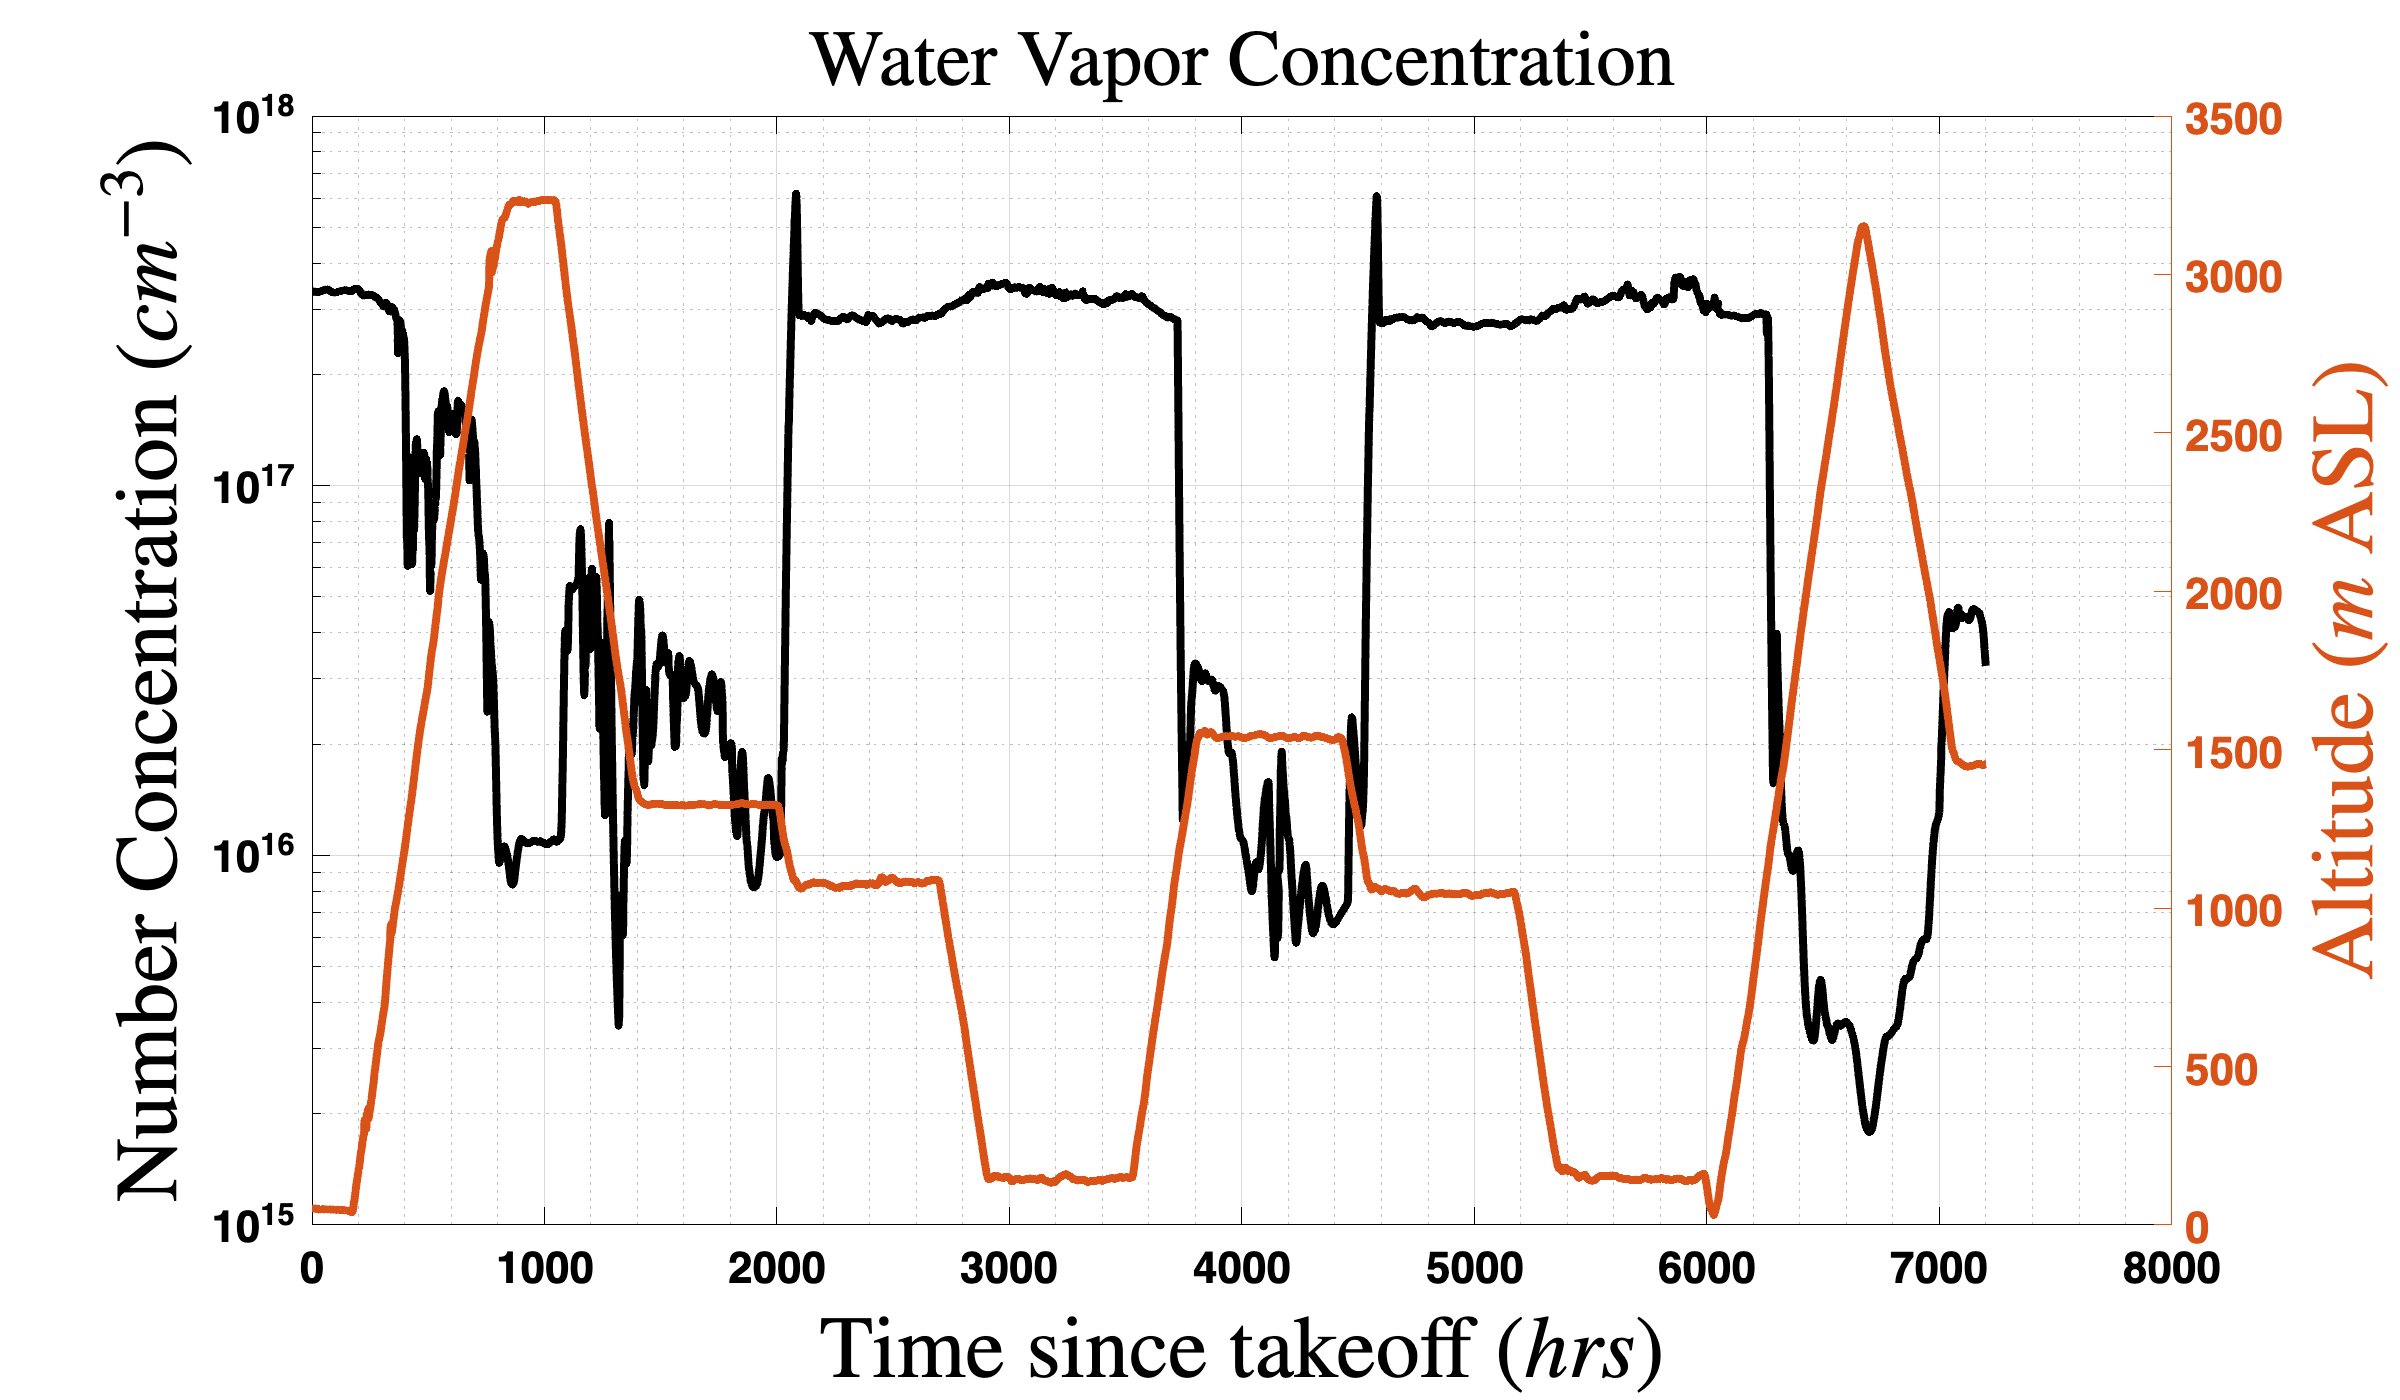

% open physical constants library
con = physical_constants;



% compute number concentration from absolute humidity
vocalsRex.Nc_vapor = vocalsRex.absolute_humidity .* (con.N_A/(con.Mol_mass_h20_vap*1e3));       % # of molecules/m^3

% convert units to inverse cubic cm
vocalsRex.Nc_vapor = vocalsRex.Nc_vapor ./ 1e6;                                                 % # of molecules/cm^3

% try computing number concentration from the partial pressure as well
vocalsRex.Nc_vapor_pp = (vocalsRex.vapor_pressure.*1e2) .* (con.N_A./(con.R_uni * (vocalsRex.temp + 273.15)));     % # of molecules / m^3

% convert units to inverse cubic cm
vocalsRex.Nc_vapor_pp = vocalsRex.Nc_vapor_pp ./ 1e6;                                                 % # of molecules/cm^3

% Let's plot the first 2 hours of water vapor measurements versus time, along with altitude
idx_time = (vocalsRex.time<7200);
figure; 
semilogy(vocalsRex.time(idx_time), vocalsRex.Nc_vapor(idx_time), 'k')
xlabel('Time since takeoff ($hrs$)', 'Interpreter','latex')
ylabel('Number Concentration ($cm^{-3}$)', 'Interpreter','latex', 'FontSize',15)
title('Water Vapor Concentration', 'Interpreter','latex')
hold on;
yyaxis right
plot(vocalsRex.time(idx_time), vocalsRex.altitude(idx_time))
grid on; grid minor
ylabel('Altitude ($m$ ASL)', 'Interpreter','latex')
set(gcf, 'Position', [0 0 1200 700])

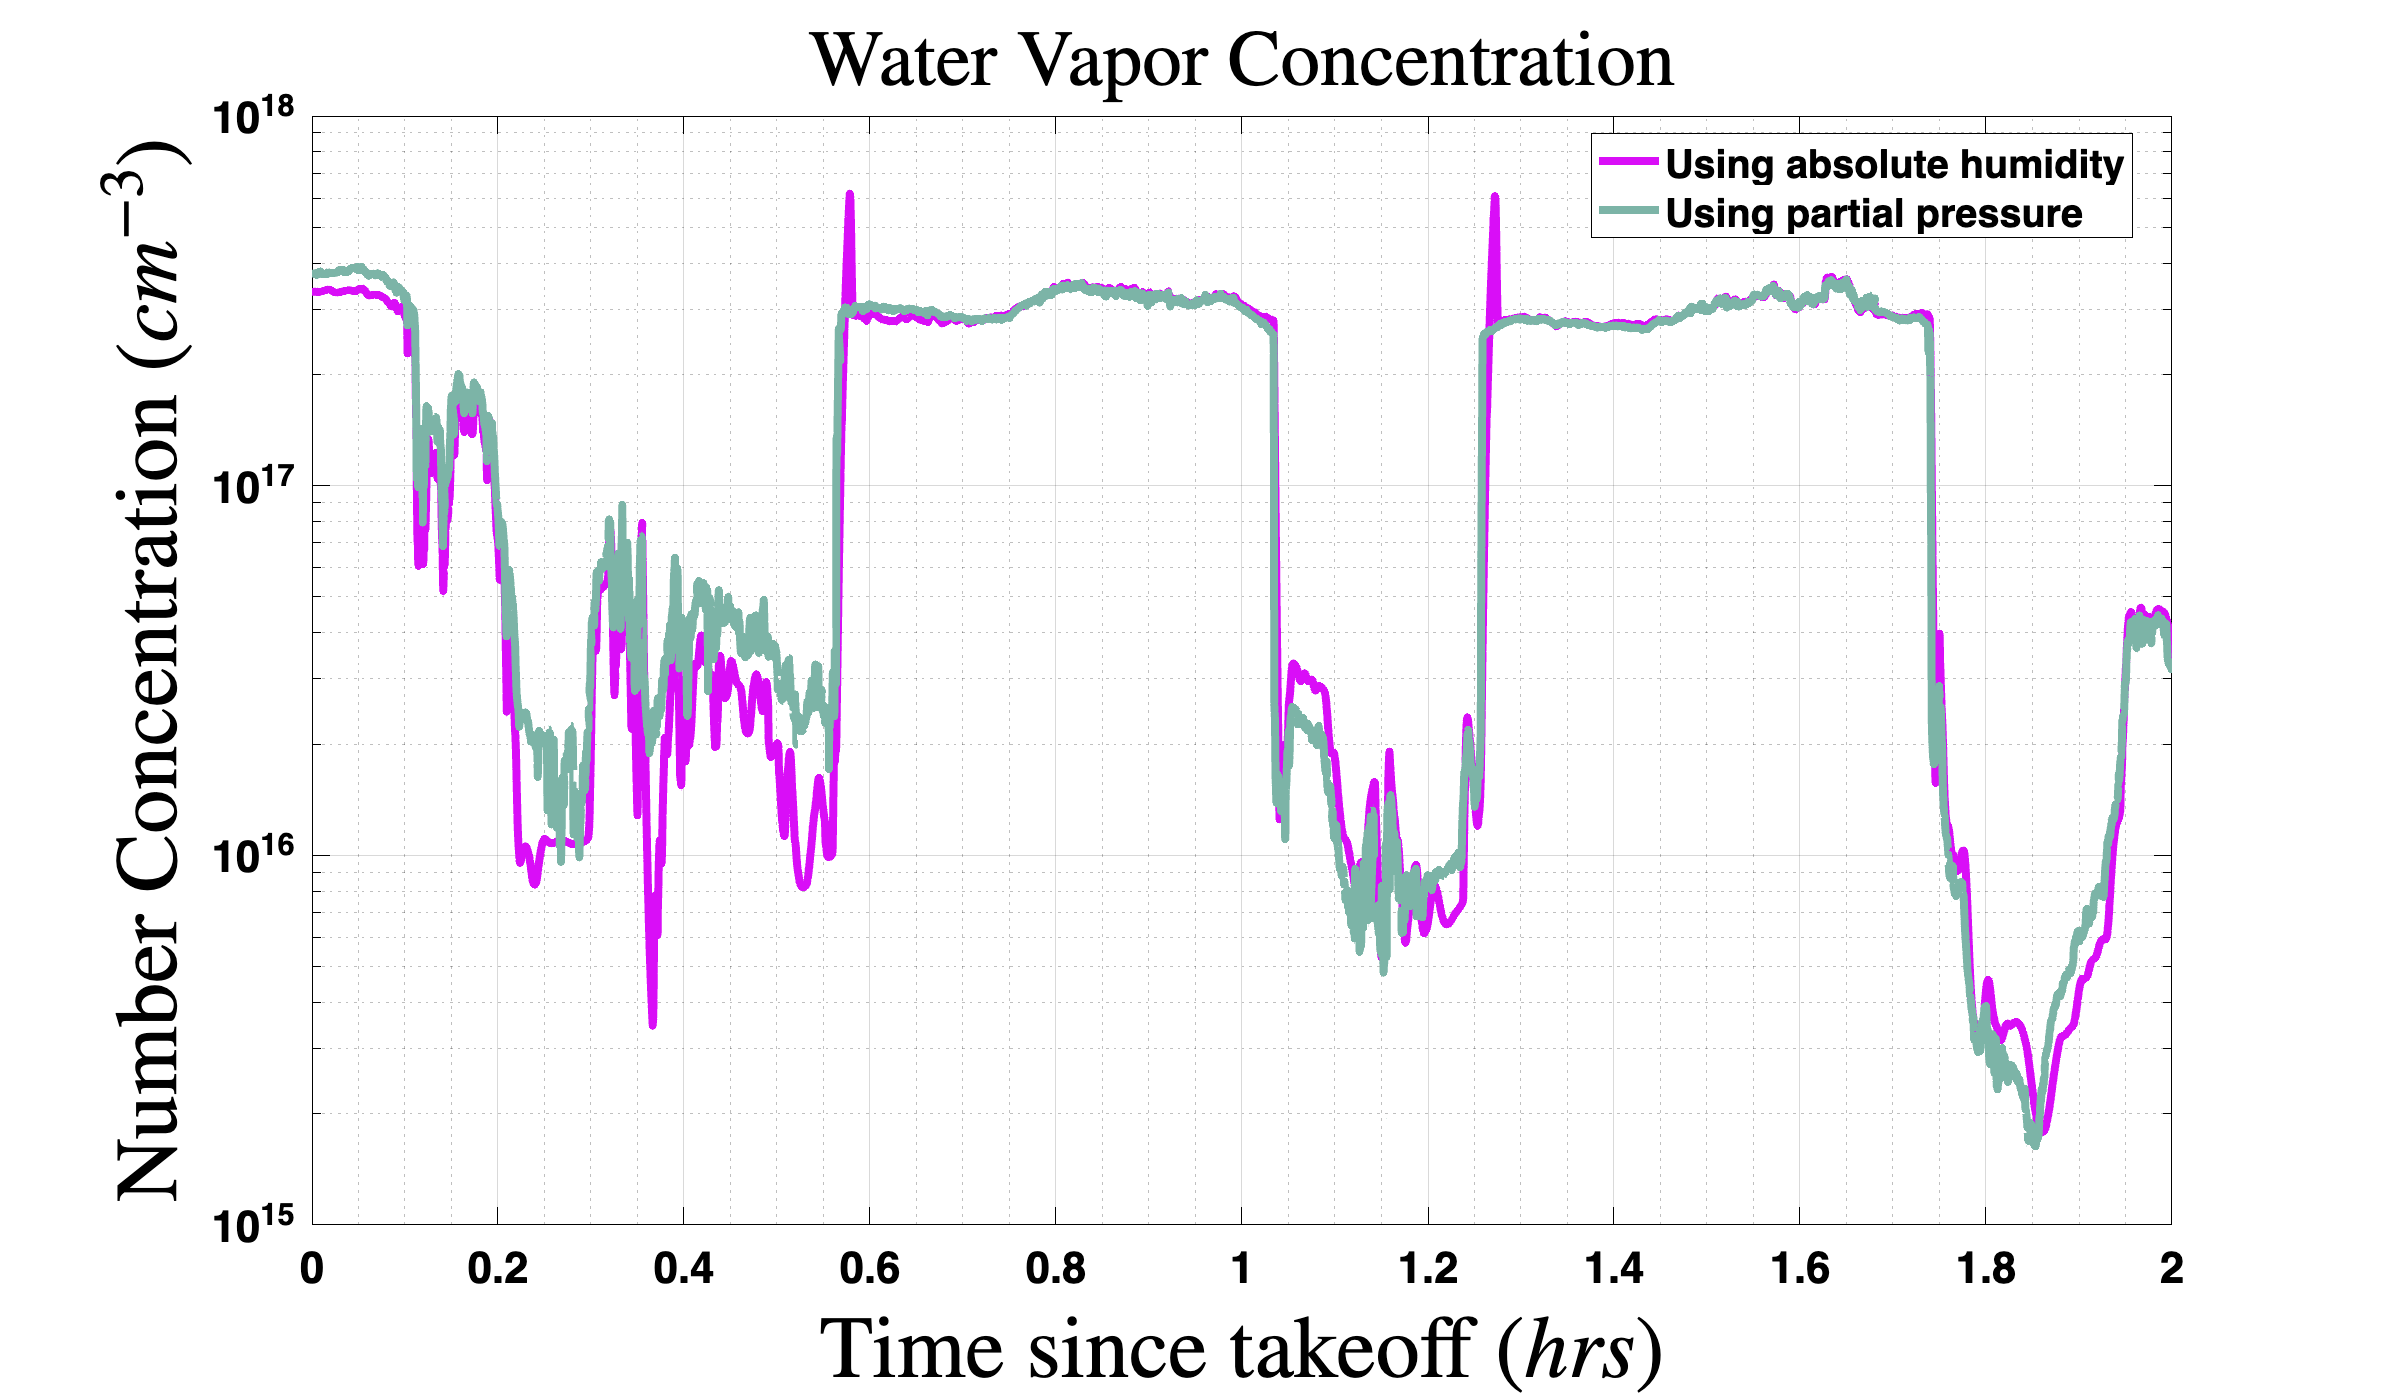

 


% Let's compare the two calculations of water vapor concentration
idx_time = (vocalsRex.time<7200);
figure; 
semilogy(vocalsRex.time(idx_time)./3600, vocalsRex.Nc_vapor(idx_time), 'color', mySavedColors(1, 'fixed'))
xlabel('Time since takeoff ($hrs$)', 'Interpreter','latex')
ylabel('Number Concentration ($cm^{-3}$)', 'Interpreter','latex')
title('Water Vapor Concentration', 'Interpreter','latex')   
hold on;
semilogy(vocalsRex.time(idx_time)./3600, vocalsRex.Nc_vapor_pp(idx_time), 'color', mySavedColors(2, 'fixed'))
grid on; grid minor
legend('Using absolute humidity', 'Using partial pressure', 'location', 'best')
set(gcf, 'Position', [0 0 1200 700])

Interesting. I don't like the anomolous spikes in number concetration that exceed the surface values when using absolute humidity. So perhaps I should trust the calculation using partial pressure more.

## Find Vertical Profiles of Clouds

Let's find all vertical profiles where the plane started below cloud and flew above, sampling along the vertical dimension

% ----- Find all vertical profiles within VOCALS-REx data ------
% find all vertical profiles in the vocals-REx data set. Vertical profiles
% qualify if the total number concentration is above 10^0 and relatively
% flat, the plane is climbing in altitude, and clears the cloud deck from
% bottom to top. If this is all true, save the vocals rex data
lwc_threshold = 0.01;           % g/m^3
stop_at_max_lwc = false;         % truncate profile after the maximum lwc value
Nc_threshold = 1;               % # droplets/cm^3


% Lets only keep the vocalsRex data we need
% Time is measured in seconds since the startTime

% ---- DO YOU WANT TO USE ADVECTION? -----
modisInputs.flags.useAdvection = true;


% ----- Find all vertical profiles within VOCALS-REx data ------
tic
vert_prof = find_verticalProfiles_VOCALS_REx(vocalsRex, lwc_threshold, stop_at_max_lwc, Nc_threshold);toc

Elapsed time is 113.267622 seconds.


disp([newline, 'It took ', num2str(toc), ' seconds to find all vertical profiles', newline])


It took 113.2699 seconds to find all vertical profiles



## Plot a single example of water vapor concentration below, within and above cloud